# Testing data from laboratory's FMCW radar

#### Loading .wav file and radar parameters

[file,path] = uigetfile('*.wav');
if isequal(file,0)
   disp('User selected Cancel');
   return
else
   disp(['User selected ', file]);
end

User selected Corsa2_corner.wav



load radarParameters

#### Rearranging the data and calculating the RD map axes

dataMatrix = radarLabDataLoader(fullfile(path,file), 'trunc');
[N,M] = size(dataMatrix);
zpFactor = 4;

TimePeriod = M/samplerate;
maxR = fSamp*c*TimePeriod/(2*BW);
maxV = 0.5*lambda/(4*TimePeriod);

r = linspace(0, maxR, zpFactor*M);
v = linspace(-maxV, maxV, zpFactor*N);

#### RD map evaluation

compressoTemp = ifft(dataMatrix, zpFactor*M, 2); 
RDmap = fftshift(fft(compressoTemp, zpFactor*N), 1);

#### Plot results

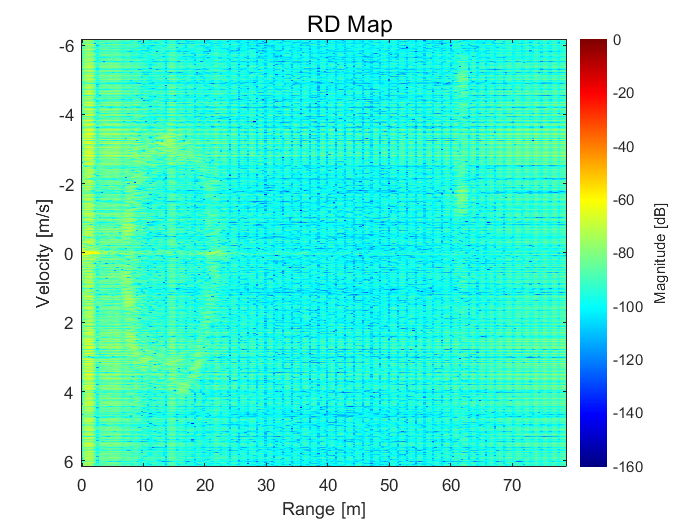

imageToPlot = 20*log10(abs(RDmap(:,1:end/2))/max(max(abs(RDmap(:,1:end/2)))));
maxDyn = max(max(imageToPlot));
minDyn = min(min(imageToPlot));

figure(2)
imagesc(r,v,imageToPlot)
c = colorbar;
c.Label.String = 'Magnitude [dB]';
colormap jet
caxis([minDyn maxDyn])
sgtitle('RD Map')
xlabel('Range [m]')
ylabel('Velocity [m/s]')

#### Windowing Function definition

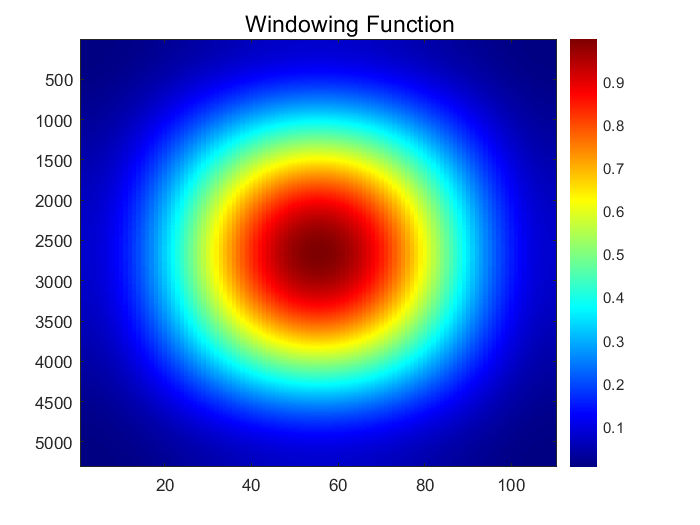

window = true;

if window
    Hn = hamming(N);
    Hm = hamming(M);
else
    Hn = ones(N,1);
    Hm = ones(M,1);
end

ham2D = repmat(Hn, 1, M).*repmat(Hm.', N, 1);
dataMatrix = dataMatrix.*ham2D;

figure(1)
imagesc(ham2D)
colormap jet
colorbar
sgtitle('Windowing Function')

#### RD map evaluation

compressoTemp = ifft(dataMatrix, zpFactor*M, 2); 
RDmap = fftshift(fft(compressoTemp, zpFactor*N), 1);

#### Plot results

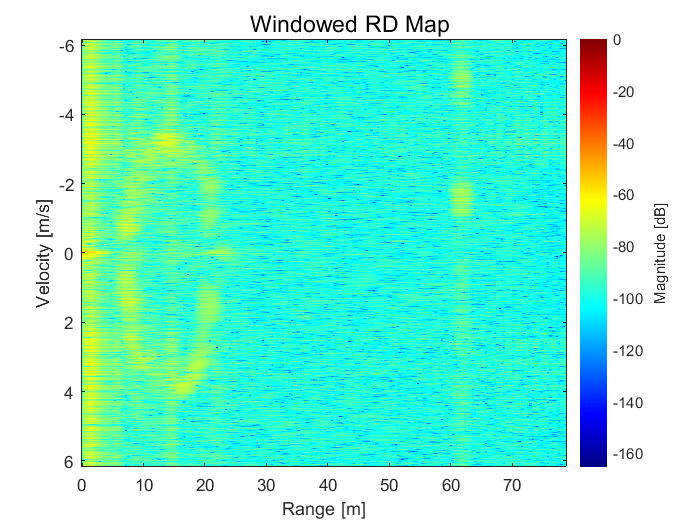

imageToPlot = 20*log10(abs(RDmap(:,1:end/2))/max(max(abs(RDmap(:,1:end/2)))));
maxDyn = max(max(imageToPlot));
minDyn = min(min(imageToPlot));

figure(2)
imagesc(r,v,imageToPlot)
c = colorbar;
c.Label.String = 'Magnitude [dB]';
colormap jet
caxis([minDyn maxDyn])
sgtitle('Windowed RD Map')
xlabel('Range [m]')
ylabel('Velocity [m/s]')

#### High-Pass Filtering and RD map evaluation

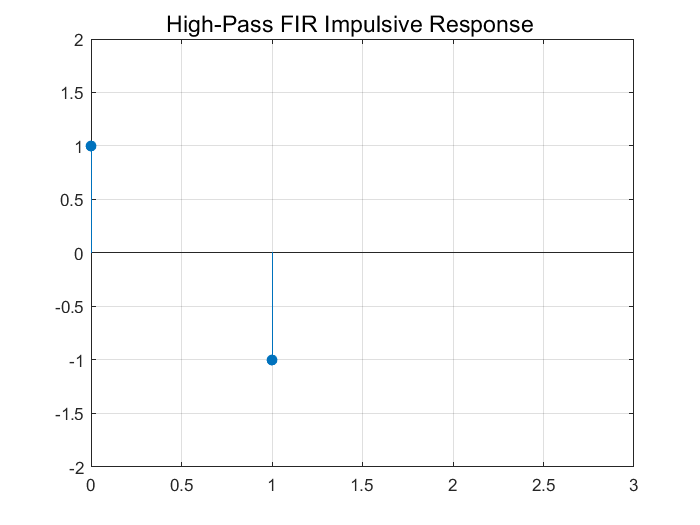

MTI_Filter = [1 -1];
filteredData = filter(MTI_Filter, 1, dataMatrix, [], 2);

compressoTemp = ifft(filteredData, zpFactor*M, 2); 
RDmap = fftshift(fft(compressoTemp, zpFactor*N), 1);

figure(3)
stem([0 1], MTI_Filter,'filled')
grid on
sgtitle('High-Pass FIR Impulsive Response')
xlim([0 3])
ylim([-2 2])

#### Plot results

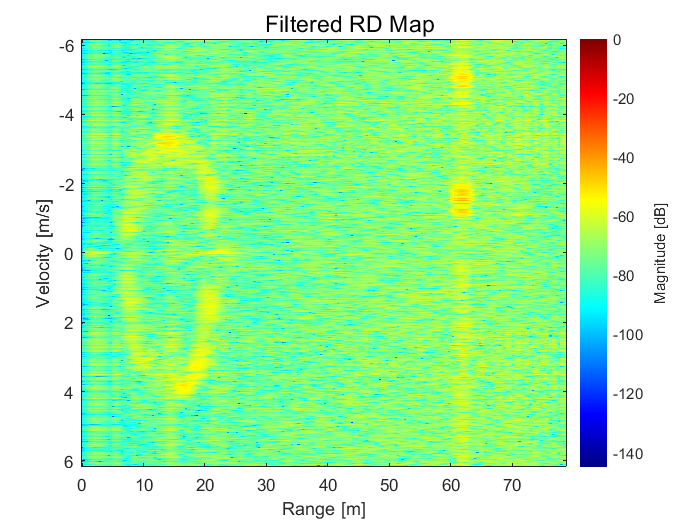

imageToPlot = 20*log10(abs(RDmap(:,1:end/2))/max(max(abs(RDmap(:,1:end/2)))));
maxDyn = max(max(imageToPlot));
minDyn = min(min(imageToPlot));

figure(4)
imagesc(r,v,imageToPlot)
c = colorbar;
c.Label.String = 'Magnitude [dB]';
colormap jet
caxis([minDyn maxDyn])
sgtitle('Filtered RD Map')
xlabel('Range [m]')
ylabel('Velocity [m/s]')